Define all constants that are to be used for model comparison, definition of input etc.

%patients that shall be taken into account
patients=[1:11,13:30];
%inputFolder='/Figures/02_24/';
%inputFolder='/Figures/03_22/'
inputFolder='/Figures/03_29/';
%input basefolder -> in that folder, for each patient must be a subfolder
%with the param table 
%inputFolder='/Figures/02_03/';
%output basefolder -> in that folder, figures will be saved, but within
%subfolders, if wanted
%outputFolder='/Figures/03_22/bicComparison/';
outputFolder='/Figures/03_24/bicComparison/';

%Basename the params are stored as -> have to be stored as basename_Pat(nr)
par_table_name="Params";
%sheet where the params are stored in
sheet=1;
%model name, defines plot title
modelName="post_therapy";
%model names, columns where model information are displayed
modelNames=["model"];
%modelNames=["model"];
%figure Ratings -> figures can be stored in those subfolders
%figureRatings=["contradiction/","no_contradiction/"];
figureRatings=["contradiction/","no_contradiction/"];

compCriteria="negLik";
minOrMax="bic";

%threshold for defining the model rating
thresholds=[0,2,6,10];
%model ratings
ratings=[0,1,2,3];
%max rating in second plot
max_rating=0;

%duplicateModels=[getDuplicateModels(1003).Variables',getDuplicateModels(2003).Variables'];
duplicateModels=[];

nonrejected_models=[];

%params that define a model to remove the duplicate model structures
%model_def_param_names=["d_PB","d_LT","d_BM","m_LT_PB","m_PB_LT","m_BM_PB","m_PB_BM","m_LT_BM","m_BM_LT","LT_healthy","Blood_healthy","BM_healthy"];
%model_def_param_names=["d_PB","d_LT","d_BM","m_LT_PB","m_PB_LT","m_BM_PB","m_PB_BM","m_LT_BM","m_BM_LT","g_PB_all","g_all_PB"];
model_def_param_names=["d_PB","d_LT","m_LT_PB"];

%params that define the pathways between the compartments
%pathway_names=["m_LT_PB","m_PB_LT","m_BM_PB","m_PB_BM","m_LT_BM","m_BM_LT","g_all_PB","g_PB_all"];
pathway_names=["m_LT_PB"];


Create folders that shall be used to save the figures

if ~isempty(figureRatings)
    inputText="Choose folder: "
    for f=figureRatings
        mkdir(strcat(outputFolder(2:end),f));
        inputText=inputText+f+"   ";
    end
else
    mkdir(outputFolder(2:end));
end

inputText = "Choose folder: "

First patient is used to analyse the model structure and the available compCriterias.

patient=patients(1);
pat_table=readtable(strcat(pwd,inputFolder,'patient_',int2str(patient),'/',par_table_name,'_Pat',int2str(patient),'.xlsx'),"Sheet",sheet);


Give the option to choose between available CompCriterias.

disp("Variables available: ");

Variables available: 


pat_table.Properties.VariableNames

ans = 1×31 cell array
    {'model'}    {'model_pre'}    {'ACC'}    {'d_PB'}    {'d_LT'}    {'m_LT_PB'}    {'LT_0'}    {'PB_0'}    {'LT_healthy'}    {'d_BM'}    {'m_BM_PB'}    {'BM_0'}    {'BM_healthy'}    {'m_LT_BM'}    {'Blood_healthy'}    {'m_PB_LT'}    {'m_PB_BM'}    {'m_BM_LT'}    {'sd_x'}    {'sd_y'}    {'sd_z'}    {'sd_hb'}    {'PB_pre_0'}    {'g'}    {'negLik'}    {'bic'}    {'aicr'}    {'likelihood'}    {'bic_TwoComp'}    {'aicr_TwoComp'}    {'likelihood_TwoComp'}



compCriteria=input("Choose criteria")

compCriteria = 'bic'

minOrMax=input("Is the best min or max?")

minOrMax = 'min'

names=pat_table.Properties.VariableNames;
if ~isempty(find(names=="model_combined", 1))
    model_names=names(~cellfun(@isempty,regexp(names,"model_combined")));
else
     model_names=modelNames;
end

Remove the duplicate model structures

%models=prod(unique(pat_table(:,model_names)).Variables',1);
models=unique(pat_table(:,model_names)).Variables;
%model_def_params=array2table([models,zeros(length(models),length(model_def_param_names))],'VariableNames',["model",model_def_param_names]);

model_def_params=[array2table(models),array2table(zeros(length(models),length(model_def_param_names)))];
model_def_params=renamevars(model_def_params,1:width(model_def_params),["model",model_def_param_names]);
%duplicateModels=[];
for model = models'
%    model_params=pat_table(prod(unique(pat_table(:,model_names)).Variables',1)==model,:);
    model_params=pat_table(string(pat_table.model)==string(model),:);
    model_def_params(string(model_def_params.model)==string(model),model_def_param_names)=array2table((model_params(1,model_def_param_names).Variables>0),'VariableNames',model_def_param_names);
end
% threeCompModels=model_def_params(model_def_params.model>2,:);
% for i = 1:length(threeCompModels.model)
%     p_model=threeCompModels.model(i);
%     for j = (i+1):length(threeCompModels.model)
%         d_model=threeCompModels.model(j);
%         if isempty(find(~(threeCompModels(threeCompModels.model==d_model,model_def_param_names).Variables==threeCompModels(threeCompModels.model==p_model,model_def_param_names).Variables), 1))
%             duplicateModels=[duplicateModels,d_model];
%         end
%     end
% end
% for model=duplicateModels
%     model_def_params=model_def_params(model_def_params.model ~=model,:);
%     pat_table=pat_table(pat_table.model~=model,:);
% end

pathways=model_def_params(:,["model",pathway_names]);

Remove duplicate runs

pat_table=getBestRuns(pat_table,compCriteria,minOrMax);

Create the table that ranks the models, based on the chosen compCriteria.

Plus, a matrix is created that shows the model structures.

bestMeasure=getBestMeasure(pat_table, compCriteria,minOrMax);

measure=pat_table(:,compCriteria);
rank=ratings(sum(abs(measure.Variables-bestMeasure)>=thresholds,2))';
compTable=table(pat_table.ACC,pat_table(:,modelNames).Variables,measure.Variables,rank,'VariableNames',["ACC","model","compCriteria","rating"]);

for patient=patients(2:end)
    pat_table=readtable(strcat(pwd,inputFolder,'patient_',int2str(patient),'/',par_table_name,'_Pat',int2str(patient),'.xlsx'),"Sheet",sheet);

    for model=duplicateModels
        pat_table=pat_table(pat_table.model~=model,:);
    end
    pat_table=getBestRuns(pat_table,compCriteria,minOrMax);
    bestMeasure=getBestMeasure(pat_table, compCriteria,minOrMax);
    measure=pat_table(:,compCriteria);
    rank=ratings(sum(abs(measure.Variables-bestMeasure)>=thresholds,2))';
    compTable=union(compTable,table(pat_table.ACC,pat_table(:,modelNames).Variables,measure.Variables,rank,'VariableNames',["ACC","model","compCriteria","rating"]));

end

%compTable=compTable(compTable.model>2000,:);

f=clf;
%h=heatmap([1:11,13:30],1:79,compTable(model,"compCriteria"));
matrix=zeros(size(compTable,1)/length(patients),length(patients));
for i=1:length(patients)
    matrix(:,i)=compTable(compTable.ACC==patients(i),"rating").Variables;
end

names=pat_table.Properties.VariableNames;

if ~isempty(find(names=="model_combined", 1))
    model_names=names(~cellfun(@isempty,regexp(names,"model_combined")));
% else
%     model_names=names(~cellfun(@isempty,regexp(names,"model")));
end


%f=heatmap(patients,unique(compTable.model)',matrix);
f=heatmap(patients,unique(pat_table(:,model_names).Variables'),matrix,"Visible","on");
plotTitle="BIC comparison, HB model";
title(plotTitle);
f.ColorLimits = [0 3];
f.Colormap=winter(4)

f =   HeatmapChart (BIC comparison, HB model) with properties:

        XData: {29×1 cell}
        YData: {3×1 cell}
    ColorData: [3×29 double]

  Show all properties


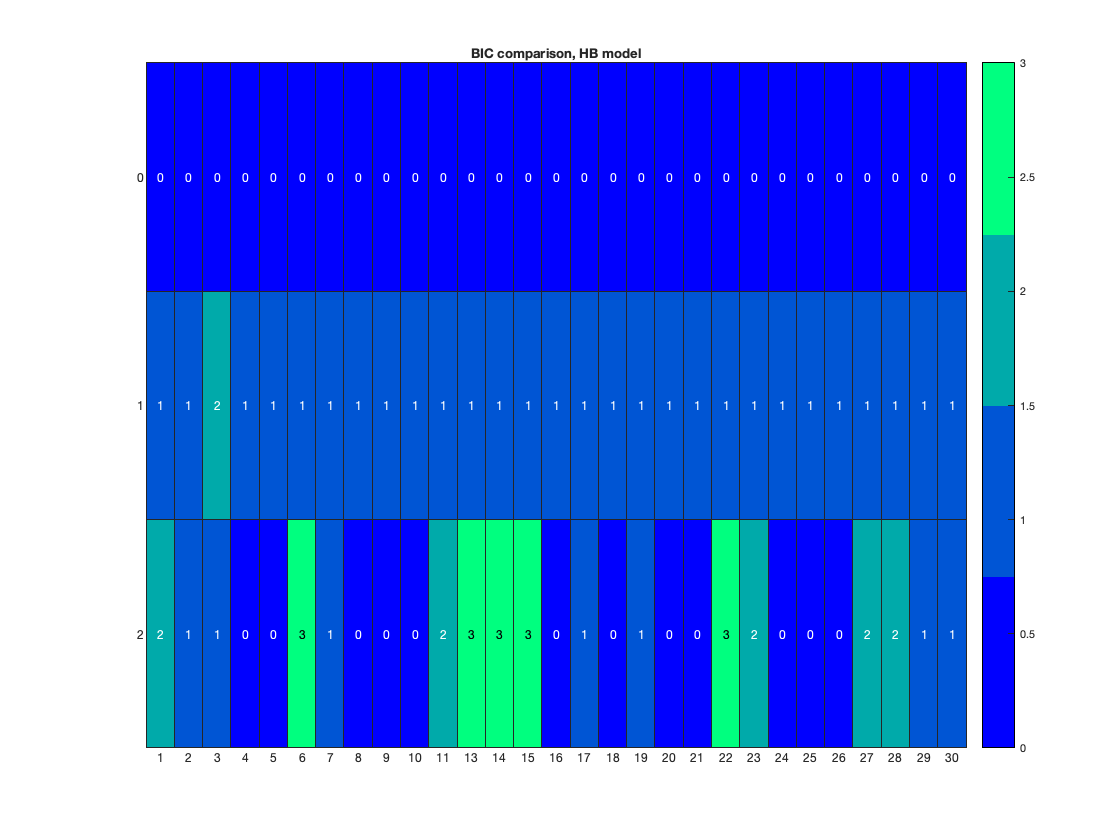

f.FontSize=6;

Create the plots.

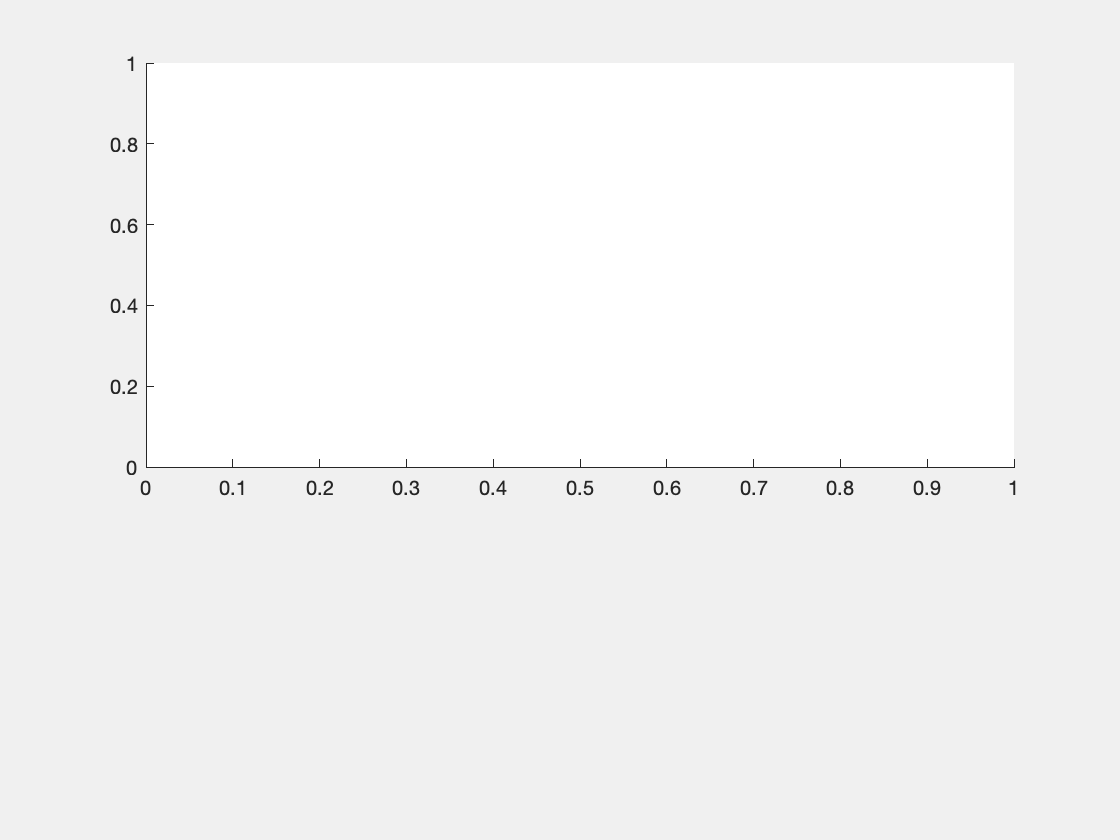

Error using gobjects (line 79)
Size vector should be a row vector with integer elements.

Error in subplot>addAxesToGrid (line 673)
        grid = gobjects(nRows,nCols);

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('subplot', '/Applications/MATLAB_R2020a.app/toolbox/matlab/graph2d/subplot.m', 607)" style="font-weight:bold">subplot</

plot_number=length(pathway_names)/2+1;
colormap=[[1 0 0];[1 1 0];[0 1 0]];

for patient=patients
    figure('Visible',"on");
    f=clf;
    subplot(plot_number,1,1);
    compPatTable=compTable(compTable.ACC==patient,:);
    compPatTable.modelProd=prod(compPatTable.model,2);
    %all Models
    h=heatmap(compPatTable,"modelProd","ACC","ColorVariable","rating");
    h.ColorLimits = [0 3];
    h.Colormap=winter(5);
    h.FontSize=6;
    plotTitle=compCriteria+" comparison, model "+modelName+", patient "+int2str(patient);
    title(plotTitle);
    counter=2;
    for p=1:2:length(pathway_names)
        subplot(plot_number,1,counter);
        pathway=split(pathway_names(p),"_");
        
        yvalues={pathway(2)+" to "+pathway(3)};
        xvalues=pathways.model;
        h=heatmap(xvalues,yvalues,(pathways.(pathway_names(p))-pathways.(pathway_names(p+1)))');
%         addYLabel(h,)
        h.ColorLimits = [-1 1];
        h.Colormap=colormap;
        h.FontSize=6;
    
    
        %plotTitle="BIC comparison,HB model, patient "+int2str(patient);
        %title(plotTitle);
        counter=counter+1;
    end
    %only non rejected
    figure('Visible','on')
    f=clf;
    subplot(plot_number,1,1);
    compPatTable=sortrows(compPatTable,"model");
    compPatTable.model=compPatTable.modelProd;
    h2=heatmap(compPatTable(compPatTable.rating<=max_rating,:),"model","ACC","ColorVariable","rating");
    h2.ColorLimits = [0 2];
    h2.Colormap=winter(5);
    h2.FontSize=6;
    plotTitle=compCriteria+" comparison, model "+modelName+", patient "+int2str(patient);
    title(plotTitle);
    counter=2;
    pat_pathways=join(compPatTable,pathways);
    for p=1:2:length(pathway_names)
        subplot(plot_number,1,counter);
        pathway=split(pathway_names(p),"_");
        
        rel_pathways=pat_pathways(pat_pathways.rating<=max_rating,:);
        
        yvalues={pathway(2)+" to "+pathway(3)};
        xvalues=rel_pathways.model;
        h2=heatmap(xvalues,yvalues,(rel_pathways.(pathway_names(p))-rel_pathways.(pathway_names(p+1)))');
%         addYLabel(h,)
        h2.ColorLimits = [-1 1];
        h2.Colormap=colormap;
        h2.FontSize=6;
        %plotTitle="BIC comparison,HB model, patient "+int2str(patient);
        %title(plotTitle);
        counter=counter+1;
    end
    
    if ~isempty(figureRatings)
        x=input(inputText);
        savefig(f,strcat(pwd,outputFolder,x,"/patient_",int2str(patient)),'compact');
    else
        savefig(f,strcat(pwd,outputFolder,"/patient_",int2str(patient)),'compact');
    end
    close;
end